# Object Detection and Explainability with PyTorch Model Using Co-Execution

## Python Environment

Set up the Python® environment by first running commands at a command prompt (Windows® machine) and then, set up the Python interpreter in MATLAB.

Go to your working folder. Create the Python virtual environment `venv` in a command prompt outside MATLAB. If you have multiple versions of Python installed, you can specify which Python version to use for your virtual environment.

Activate the Python virtual environment `env` in your working folder.

Install the necessary Python libraries for this example. Check the installed versions of the libraries.

Set up the Python interpreter for MATLAB® by using the [`pyenv`](https://www.mathworks.com/help/matlab/ref/pyenv.html) function. Specify the version of Python to use.

pe = pyenv(Version=".\env\Scripts\python.exe",ExecutionMode="OutOfProcess")

pe =   PythonEnvironment with properties:

          Version: "3.11"
       Executable: "C:\Users\sparaske\OneDrive - MathWorks\Documents\AI_Customers\Demos\PyTorch_object_detection\code\env\Scripts\python.exe"
          Library: "C:\Users\sparaske\AppData\Local\Programs\Python\Python311\python311.dll"
             Home: "C:\Users\sparaske\OneDrive - MathWorks\Documents\AI_Customers\Demos\PyTorch_object_detection\code\env"
           Status: NotLoaded
    ExecutionMode: OutOfProcess


## Object Detection

Read the image that you want to use for object detection.

img_filename = "testCar.png";
img = imread(img_filename);

Perform object detection with a PyTorch model using co-execution.

pyrun("from PT_object_detection import loadPTmodel, detectPT")
[model,weights] = pyrun("[a,b] = loadPTmodel()",["a" "b"]);
predictions = pyrun("a = detectPT(b,c,d)","a",b=img,c=model,d=weights);

Convert the prediction outputs from Python data types to MATLAB data types.

[bboxes,labels,scores] = convertVariables(predictions,imread(img_filename));

Get the class labels.

class_labels = getClassLabels(labels);

## Visualization

Create the labels associated with each of the detected objects.

num_box = length(scores);
colons = repmat(": ",[1 num_box]);
percents = repmat("%",[1 num_box]);
class_labels1 = strcat(class_labels,colons,string(round(scores'*100)),percents);

Visualize the object detection results with annotations.

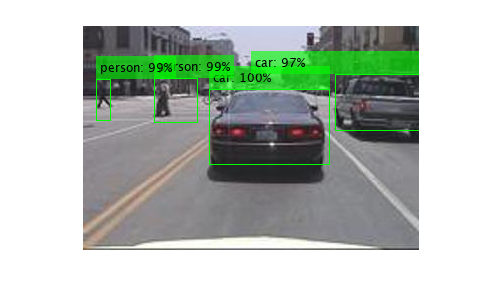

figure
outputImage = insertObjectAnnotation(img,"rectangle",bboxes,class_labels1,LineWidth=1,Color="green");
imshow(outputImage)

## Explainability

Explain the predictions of the PyTorch model using D-RISE. Specify a custom detection function to use D-RISE.

targetBbox = bboxes(1,:);
targetLabel = 1;
scoreMap = drise(@(img)customDetector(img),img,targetBbox,targetLabel,...
    NumSamples=512,MiniBatchSize=8,Verbose=true);

Explaining 1 detections.
Number of mini-batches to process: 64
..........   ..........   ..........   ..........   .......... (50 mini-batches)
..........   ....                                              (64 mini-batches)
Total time = 1145.9secs.


Plot the results.

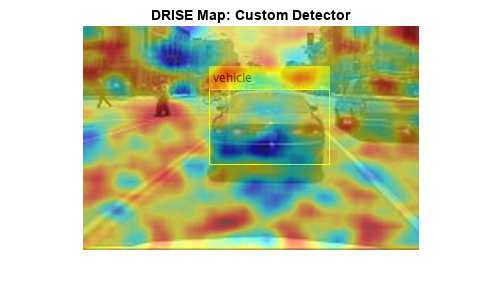

figure
annotatedImage = insertObjectAnnotation(img,"rectangle",targetBbox,"vehicle");
imshow(annotatedImage)
hold on
imagesc(scoreMap,AlphaData=0.5)
title("DRISE Map: Custom Detector")
hold off
colormap jet